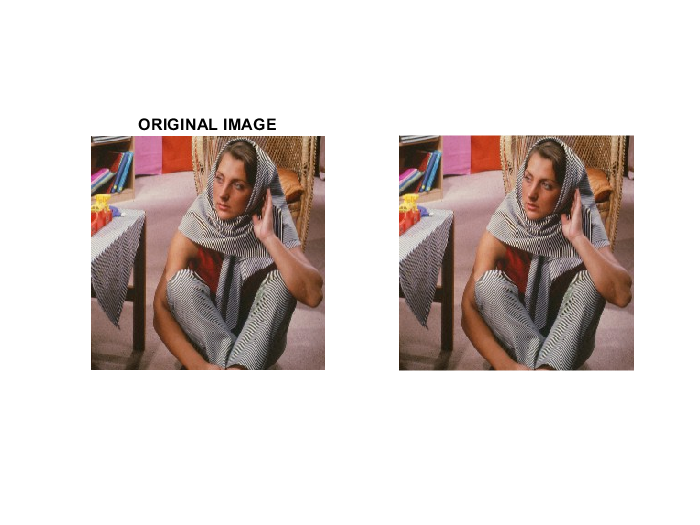

clc;
clear all;
load('images/5/barbara.mat');
imshow(barbara)

όπως φαίνεται έπειτα την φόρτωση της εικόνας προκύπτει ένας πίνακας 3 διαστάσεων και αυτό οφείλεται στο ότι η εικόνα είναι έγχρωμη με 256χ256χ1 να αντιστοιχεί στο κόκκινο , με 256χ256χ2 να αντιστοιχεί στο πράσινο και 256χ256χ3 στο μπλε. Για να εμφανιστούν τα ιστογράμματα γίνονται με την εντολή hist() της matlab . Για να προσαρμόσουμε την αντίθεση ( contrast ) χρησιμοποιείται  histogram equalization με την έτοιμη συνάρτηση της matlab την `histeq()` 

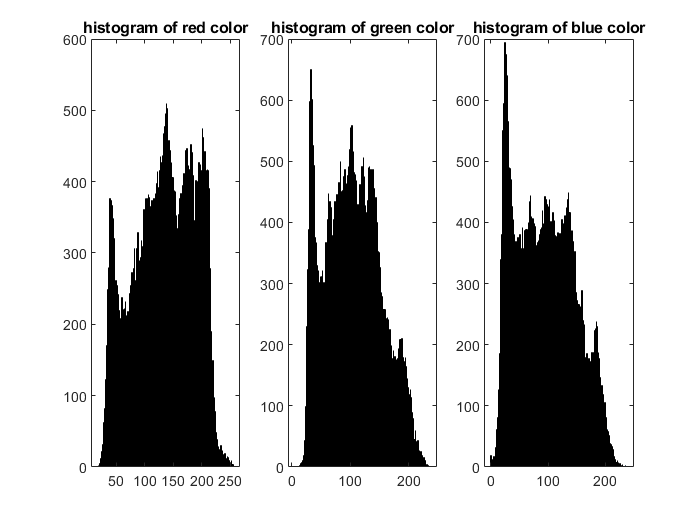

figure()

subplot(1,3,1)
hist1=histogram(barbara(:,:,1),255);
title('histogram of red color')

subplot(1,3,2)
hist2=histogram(barbara(:,:,2),255);
title('histogram of green color')

subplot(1,3,3)
hist3=histogram(barbara(:,:,3),255);
title('histogram of blue color')

## histogram Equalization  σε rgb εικόνα

PMF

Πρώτα πρέπει να υπολογίσουμε το PMF (συνάρτηση μάζας πιθανότητας) όλων των pixel αυτής της εικόνας. Τώρα, εάν πρέπει να υπολογίσουμε το PMF του ιστογράμματος, θα κοιτάξουμε απλώς το πλήθος κάθε ράβδου από τον κατακόρυφο άξονα και στη συνέχεια θα το διαιρέσουμε με το συνολικό πλήθος.

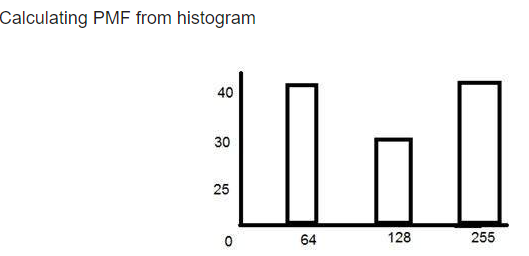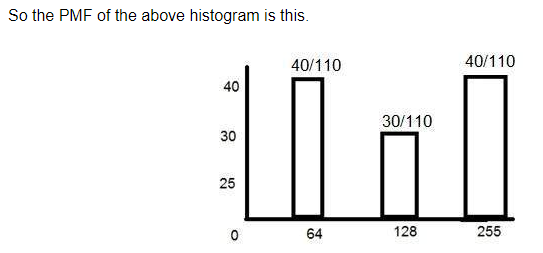

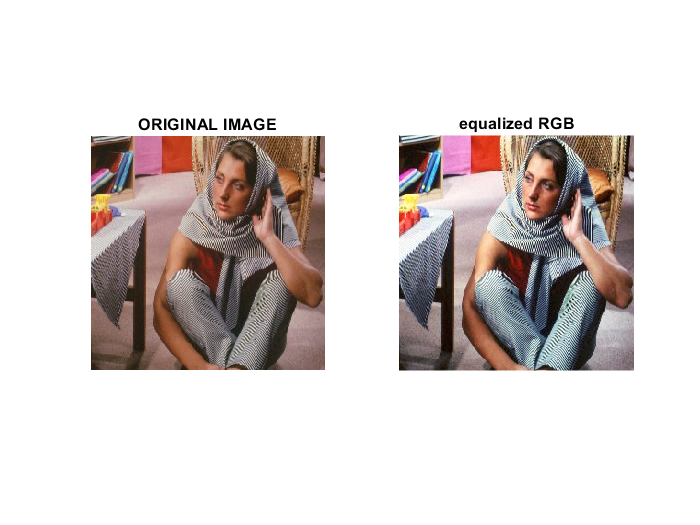

counter=0;
for histx=[hist1 hist2 hist3]
    counter=counter+1;
    temp=[];
    hist=histx;
    counts = hist.Values;
    for j=1:length(counts)
        if j==1
            temp(j)=counts(1);
        
        else 
            temp(j)=counts(j)+temp(j-1);
        end
    end
    cdf=temp./sum(counts).*255;

    for k=1:size(cdf,2)
        for j=1:size(cdf,2)
            new_image(k,j,counter)=cdf( barbara(k,j,counter)+1 );
        end
    end
    
end    
figure()
subplot(1,2,1)
imshow(barbara)
title('ORIGINAL IMAGE')
subplot(1,2,2)
imshow(uint8(new_image))
title('equalized RGB')

CDF

Το επόμενο βήμα μας περιλαμβάνει τον υπολογισμό του CDF (αθροιστική διανεμητική συνάρτηση).Θα υπολογίσουμε το CDF χρησιμοποιώντας ένα ιστόγραμμα. Εδώ πώς γίνεται. Εξετάστε το ιστόγραμμα που φαίνεται παραπάνω που δείχνει PMF.Δεδομένου ότι αυτό το ιστόγραμμα δεν αυξάνεται μονοτονικά, έτσι θα το κάνει μονοτονικό.Θα κρατήσουμε απλά την πρώτη τιμή ως έχει, και στη συνέχεια στη 2η τιμή, θα προσθέσουμε την πρώτη και ούτω καθεξής.

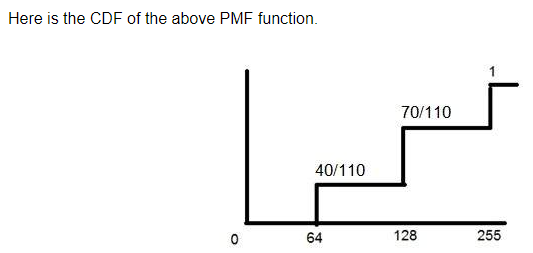

Επειδή δεν μπορούμε να εφαρμόσουμε histogram Equalization σε κάθε κανάλι χρώματος ξεχωριστά περνάμε σε HSV/HSI ColorMap όπου αποτελείται από 3 components  το Hue , τo Saturation και το Value/INTE. Εμάς μας ενδιαφέρει το Value το οποίο εκφράζει το επίπεδο η την ένταση χρώματς. Χρησιμοποιούμε την έτοιμη συνάρτηση της matlab την histeq () για histogram Equalization με είσοδο το διάνυσμα value που το έχουμε θέσει v1 και έπειτα ξαναγυρνάμε στο πεδίο rgb αφού έχουμε τροποποιήσει το 3ο component Value.

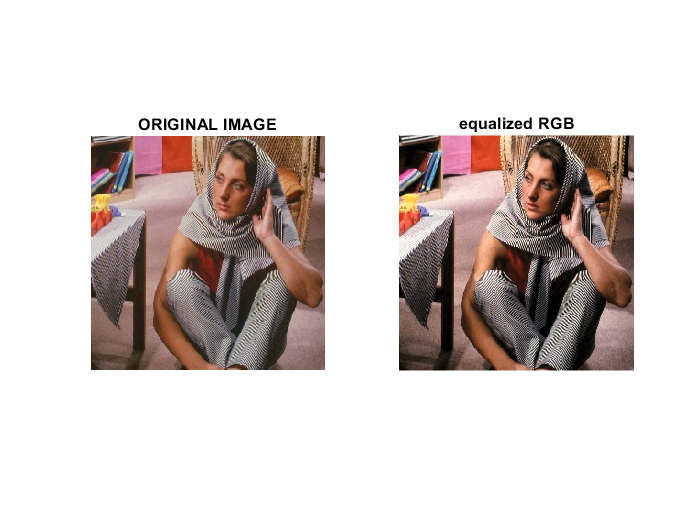

figure()
barbara_hsv=rgb2hsv(barbara);
v1=barbara_hsv(:,:,3); % the third component that it is Value decides the
% level or the intensity of the color
v1=histeq(v1);

figure()
barbara_hsv(:,:,3)=v1;
barbara_new=hsv2rgb(barbara_hsv);
subplot(1,2,1)
imshow(barbara)
title('ORIGINAL IMAGE')
subplot(1,2,2)
imshow(barbara_new)
title('equalized RGB')

## Adaptive Histogram Equalization 

**είναι μια τεχνική επεξεργασίας εικόνας που χρησιμοποιείται για τη βελτίωση της αντίθεσης στις εικόνες. Διαφέρει από τη συνήθη εξίσωση ιστογράμματος από την άποψη ότι η προσαρμοστική μέθοδος υπολογίζει πολλά ιστογράμματα, το καθένα αντιστοιχεί σε ένα ξεχωριστό τμήμα της εικόνας και τα χρησιμοποιεί για να αναδιανείμει τις τιμές φωτεινότητας της εικόνας. Είναι επομένως κατάλληλο για τη βελτίωση της τοπικής αντίθεσης και την ενίσχυση των ορισμών των άκρων σε κάθε περιοχή μιας εικόνας. Ωστόσο, η αργή ταχύτητα και η αύξηση του θορύβου που παράγει σε σχετικά ομοιογενείς περιοχές είναι δύο προβλήματα**

Στον παραπάνω κώδικα εφαρμόστηκε ακριβώς η ίδια μεθοδολογία με το total histogram equalization με την διαφορά ότι κάθε φορά εφαρμόζεται σε ένα παράθυρο και το αποτέλεσμα τοποθετείται στο καινούρια πίνακα κάθε φορά ο οποίος και εμφανίζεται. Έπειτα απο διάφορες δοκιμές κατέληξα σε παράθυρο μεγέθους 32χ32.

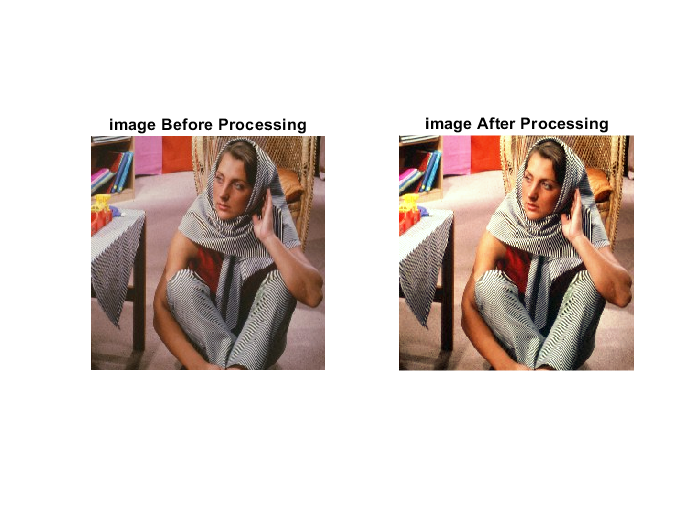

counter_x=0;
counter_y=0;
temp=[];
win_size=32;

new_image_2=[];

for channel=[1 2 3]
    for parathura =1:64
        if mod(parathura,8)==1 && parathura~=1
           counter_x=counter_x+1;
           counter_y=0;  
        end
        window(:,:)=barbara(1+counter_x : win_size+counter_x , 1+counter_y : win_size+counter_y,channel);
        
        hist=zeros(256,1);
        for i=window(:)
            hist(i+1)=hist(i+1)+1;
        end
        hist=hist/(256*256);
        
        temp=[];
        for i=1:size(hist,1)
            if i==1
                temp(1)=hist(1);
            else
                temp(i)=hist(i)+temp(i-1);
            end
        end
        cdf=temp./sum(hist).*255;
        for i=1:256
            for j=1:256
               new_image_2(i,j,channel)=cdf( barbara(i,j,channel) +1);
            end
        end    
        counter_y=counter_y+1;
    end       
end


figure()
subplot(1,2,1);
imshow(barbara);
title(sprintf("image Before Processing"))
subplot(1,2,2);
imshow(uint8(new_image_2));
title(sprintf("image After Processing"))

Φορτώνεται η εικόνα circle.mat. Ενώ καταφέρνω να δημιουργήσω την μάσκα - παράθυρο με ένα μικρότερι μέγεθος  αντιμετωπίζω κάποιο  πρόβλημακαι δεν καταφέρνω να το ολοκληρώσω.

figure()
load('images/5/circle.mat');
counterx=0;
countery=0;
blocks={};
for i=1:64
    if mod(i,8) && i~=1
        counterx=counterx+8;
    end
    blocks{i}=circle(1+counterx: 8+counterx , 1+countery:8 +countery);
    countery=countery+8;
end

Index in position 2 exceeds array bounds (must not exceed 256).

for i=1:length(blocks)
    blocks_adapt{i}=adapthisteq(blocks{i});
end

matrix=zeros(256,256);
counterx=0;
countery=0;
for i=1:length(blocks_adapt{i})
    if mod(i,8)==1 && i~=1
      counterx=counterx+1; 
      countery=0;
    end
    matrix(1+counterx*8:8+counterx*8, 1+8*countery : 8+8*countery)=blocks_adapt{i};
    countery=countery+1;
end



